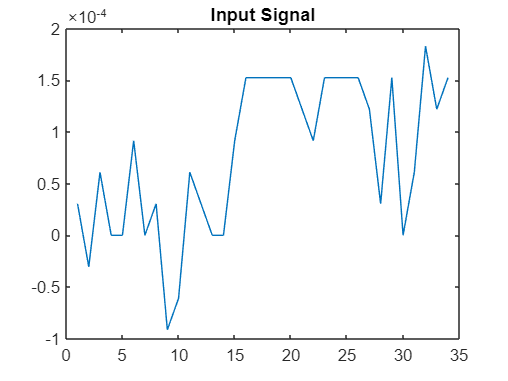

clear
t=1:1:34;
%data=exp(0.5*t);
[filename,pathname] = uigetfile('*.*','Select the input audio')
[input_sig,  orgnal_sampl_freq]=audioread(num2str(filename));
plot(t,input_sig(1:34,:))
% xlim([0 70])
title('Input Signal')

input_sig_1=input_sig(1:34,1)

input_sig_1 = 	1.0e+-3 *

    0.0305
   -0.0305
    0.0610
         0
         0
    0.0916
         0
    0.0305
   -0.0916
   -0.0610


input_sig_2=input_sig(1:34,2)

Index in position 2 exceeds array bounds. Index must not exceed 1.

plot(input_sig_1)
title('Input Signal1')
plot(input_sig_2);
title('Input Signal2')
[a,~]=size(input_sig);
time=(a/orgnal_sampl_freq);
fs=round(time);

samples=round(linspace(1,a,fs));                                               %To get n samples we divide data by n-1 so to get n points(samples)    %Input signal divided into samples with each sample separated by sample_size
sampled_signal=zeros(1,fs);       
index=1;
for i=samples
        
    sampled_signal(index)=input_sig(i);
	index=index+1;
    
end
plot(t,sampled_signal,'LineWidth',1.5);
title('y(n)');
xlabel('n');
data = sampled_signal
y = compand(data,255,max(data),'mu/compressor');
n=1;m=6;
o=1;
while ( m< length(t))
    
    D=(y(m)+y(n))/2;
    k=round((m+n)/2);
    N=y(k);
    f=N/D;
    if f >1
    nn=m;
    mn=m+round(1.25*(m-n));
    elseif f==1
        nn=m;
        mn=m+m-n
    elseif f<1
        nn=m;
        mn=m+round(0.5*(m-n));
    end
    n=nn;
    m=mn;
    ind(o)=n;
    o=o+1;
end
plot(t,y,'LineWidth',1.5)
title('compresser(y(n))');
xlabel('n');
O=zeros(size(y));
for i=1:length(ind)-1
O(ind(i):ind(i+1))=y(ind(i+1));    
end

plot(t,O,'LineWidth',1.5);
title('Quantizes output');
xlabel('n');
ny= compand(O,255,max(O),'mu/expander');
plot(t,ny,'LineWidth',1.5)
hold on
plot(t,data,'LineWidth',1.5);
title('Expander output and y(n)');
xlabel('n');
legend('Expander','y(n)');

